clc;clear all;close all

# EVACES 2025

% Load the data

Seq = 1; % 1, 2 or 3
downSampling = 100 ;
data = load("data\Seq"+num2str(Seq)+".mat");

G1 = downsample(data.G1V3,downSampling);
G2 = downsample(data.G2V3,downSampling);
G3 = downsample(data.G3V3,downSampling);
G4 = downsample(data.G4V3,downSampling);
G5 = downsample(data.G5V3,downSampling);
time = downsample(data.Time,downSampling)';

% we calculate the delta of time
dt = time(2)-time(1);


## Prepare data for DMD

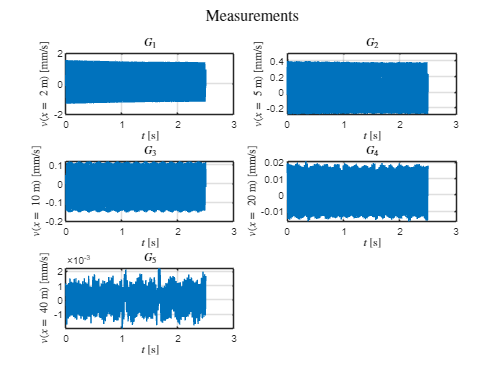

i0 = 1;
numSamples = 5000;
window = 1:numSamples;

f = [G1(window)'; G2(window)'; G3(window)'; G4(window)'; G5(window)'];
meas_points = [2 5 10 20 40];

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')
sgtitle('Measurements','Interpreter','latex')


% noise_residual = f - mean(f, 2);  % Remove signal mean
% autocorr(noise_residual(:));
% cov_matrix = cov(f');
% imagesc(cov_matrix); colorbar;  % Covariance structure
% [Pxx, f] = pwelch(noise_residual(:), [], [], [], sampling_rate);
% plot(f, 10*log10(Pxx)); xlabel('Frequency (Hz)'); ylabel('Power (dB)');


## Standard DMD

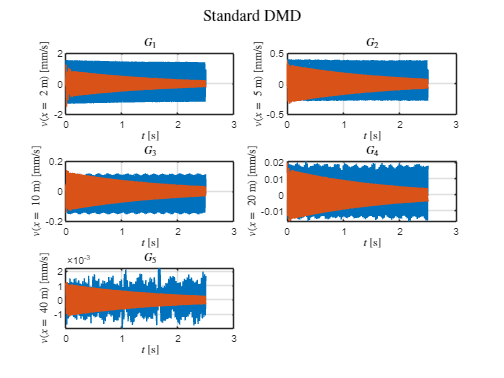

%% DMD for clean signal

% Rank truncation
r = 5;

X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_Standard = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W, D] = eig(Atilde_Standard);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi = X2 * Vr / Sr * W;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda = diag(D);
omega = log(lambda) / dt;

% Determine the initial condition (b) in DMD space
b = Phi \ X1(:, 1);

% DMD prediction
f_dmd = real(Phi*(b.*exp(omega*time(window))));

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')

sgtitle('Standard DMD','Interpreter','latex')

## AugDMD

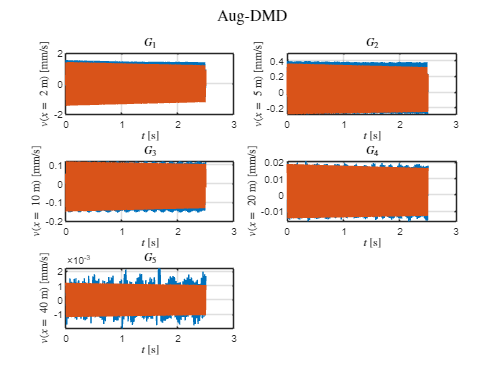


% Rank truncation
r = 5;

s = 50;
l = ceil((length(f))/2);

for i = 1:s
    f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
        f(3,i:l+i-1) ; f(4,i:l+i-1) ; f(5,i:l+i-1) ];
end

X1 = f_aug(:,1:end-1); X2 = f_aug(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U, S, V] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
Atilde_aug = Ur' * X2 * Vr *Sr^(-1);

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_aug, D_aug] = eig(Atilde_aug);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi = X2 * Vr / Sr * W_aug;

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda = diag(D_aug);
omega = log(lambda) / dt;

% Determine the initial condition (b) in DMD space
b = Phi \ X1(:, 1);

% DMD prediction
f_dmd = real(Phi*(b.*exp(omega*time(window))));

% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd(s+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd(s*2+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd(s*3+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd(s*4+1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')
sgtitle('Aug-DMD','Interpreter','latex')

## Forward-backwards DMD

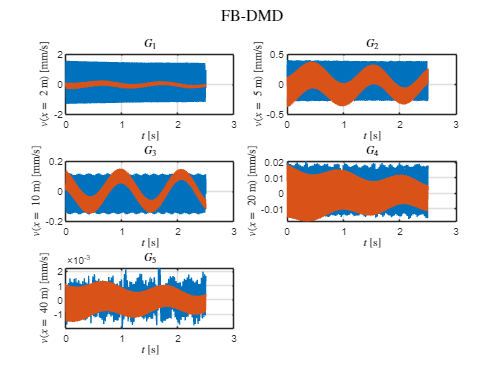

%% DMD for clean signal

% Rank truncation
r = 5;

X1 = f(:,1:end-1); X2 = f(:,2:end);

% Perform Singular Value Decomposition (SVD) on X1
[U_f, S_f, V_f] = svd(X1, "econ");

% Truncate the SVD to the desired rank 'r'
Ur_f = U_f(:, 1:r);
Sr_f = S_f(1:r, 1:r);
Vr_f = V_f(:, 1:r);

% Build the low-rank approximation of the state transition matrix Atilde
f_Atilde = Ur_f' * X2 * Vr_f *Sr_f^(-1);

[U_b, S_b, V_b] = svd(X2, "econ");

Ur_b = U_b(:, 1:r);
Sr_b = S_b(1:r, 1:r);
Vr_b = V_b(:, 1:r);

b_Atilde = Ur_b' * X1 * Vr_b *Sr_b^(-1);

% Atilde_FB = (f_Atilde*inv(b_Atilde))^0.5;
Atilde_FB = sqrtm(f_Atilde * pinv(b_Atilde));

% Compute the eigenvalues (D) and eigenvectors (W) of Atilde
[W_fb, D_fb] = eig(Atilde_FB);

% Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
Phi_fb = X2 * Vr_f / Sr_f * W_fb;
% Phi_fb = 0.5 * (X1 * Vr_f / Sr_f * W_fb + X2 * Vr_b / Sr_b * W_fb);

% Calculate the continuous-time frequencies (omega) from the eigenvalues
lambda_fb = diag(D_fb);
omega_fb = log(lambda_fb) / dt;

% Determine the initial condition (b) in DMD space
b_fb = Phi_fb \ X1(:, 1);

% DMD prediction
f_dmd_fb = real(Phi_fb*(b_fb.*exp(omega_fb*time(window))));


% Plots
figure;
subplot(3,2,1)
plot(time(window),f(1,1:end))
hold on
plot(time(window),f_dmd_fb(1,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_1$','Interpreter','latex')

subplot(3,2,2)
plot(time(window),f(2,1:end))
hold on
plot(time(window),f_dmd_fb(2,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_2$','Interpreter','latex')

subplot(3,2,3)
plot(time(window),f(3,1:end))
hold on
plot(time(window),f_dmd_fb(3,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_3$','Interpreter','latex')

subplot(3,2,4)
plot(time(window),f(4,1:end))
hold on
plot(time(window),f_dmd_fb(4,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_4$','Interpreter','latex')

subplot(3,2,5)
plot(time(window),f(5,1:end))
hold on
plot(time(window),f_dmd_fb(5,1:end))
xlabel('$t$ [s]','Interpreter','latex'); 
ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
grid on
title('$G_5$','Interpreter','latex')

sgtitle('FB-DMD','Interpreter','latex')

## Aug-FB-DMD

% %% DMD for clean signal
% 
% % Rank truncation
% r = 10;
% 
% s = 50;
% l = ceil((length(f))/2);
% 
% for i = 1:s
%     f_aug([i s+i 2*s+i 3*s+i 4*s+i],:) = [f(1,i:l+i-1) ;f(2,i:l+i-1) ;...
%         f(3,i:l+i-1) ; f(4,i:l+i-1) ; f(5,i:l+i-1) ];
% end
% 
% X1 = f_aug(:,1:end-1); X2 = f_aug(:,2:end);
% 
% %X1 = f(:,1:end-1); X2 = f(:,2:end);
% 
% % Perform Singular Value Decomposition (SVD) on X1
% [U_f, S_f, V_f] = svd(X1, "econ");
% 
% % Truncate the SVD to the desired rank 'r'
% Ur_f = U_f(:, 1:r);
% Sr_f = S_f(1:r, 1:r);
% Vr_f = V_f(:, 1:r);
% 
% % Build the low-rank approximation of the state transition matrix Atilde
% f_Atilde = Ur_f' * X2 * Vr_f *Sr_f^(-1);
% 
% [U_b, S_b, V_b] = svd(X2, "econ");
% 
% Ur_b = U_b(:, 1:r);
% Sr_b = S_b(1:r, 1:r);
% Vr_b = V_b(:, 1:r);
% 
% b_Atilde = Ur_b' * X1 * Vr_b *Sr_b^(-1);
% 
% % Atilde_aug_FB = (f_Atilde*inv(b_Atilde))^0.5;
% Atilde_aug_FB = sqrtm(f_Atilde * pinv(b_Atilde));
% % Compute the eigenvalues (D) and eigenvectors (W) of Atilde
% [W, D] = eig(Atilde_aug_FB);
% 
% % Calculate the DMD modes (Phi) using X2, Vr, Sr, and W
% Phi = X1 * Vr_f / Sr_f * W;
% 
% % Calculate the continuous-time frequencies (omega) from the eigenvalues
% lambda = diag(D);
% omega = log(lambda) / dt;
% 
% % Determine the initial condition (b) in DMD space
% b = Phi \ X1(:, 1);
% 
% % DMD prediction
% f_dmd = real(Phi*(b.*exp(omega*time(window))));
% 
% 
% % Plots
% figure;
% subplot(3,2,1)
% plot(time(window),f(1,1:end))
% hold on
% plot(time(window),f_dmd(1,1:end))
% xlabel('$t$ [s]','Interpreter','latex'); 
% ylabel("$v(x =$ "+string(meas_points(1))+" m) [mm/s]",'Interpreter','latex'); 
% grid on
% title('$G_1$','Interpreter','latex')
% 
% subplot(3,2,2)
% plot(time(window),f(2,1:end))
% hold on
% plot(time(window),f_dmd(s+1,1:end))
% xlabel('$t$ [s]','Interpreter','latex'); 
% ylabel("$v(x =$ "+string(meas_points(2))+" m) [mm/s]",'Interpreter','latex'); 
% grid on
% title('$G_2$','Interpreter','latex')
% 
% subplot(3,2,3)
% plot(time(window),f(3,1:end))
% hold on
% plot(time(window),f_dmd(s*2+1,1:end))
% xlabel('$t$ [s]','Interpreter','latex'); 
% ylabel("$v(x =$ "+string(meas_points(3))+" m) [mm/s]",'Interpreter','latex'); 
% grid on
% title('$G_3$','Interpreter','latex')
% 
% subplot(3,2,4)
% plot(time(window),f(4,1:end))
% hold on
% plot(time(window),f_dmd(s*3+1,1:end))
% xlabel('$t$ [s]','Interpreter','latex'); 
% ylabel("$v(x =$ "+string(meas_points(4))+" m) [mm/s]",'Interpreter','latex'); 
% grid on
% title('$G_4$','Interpreter','latex')
% 
% subplot(3,2,5)
% plot(time(window),f(5,1:end))
% hold on
% plot(time(window),f_dmd(s*4+1,1:end))
% xlabel('$t$ [s]','Interpreter','latex'); 
% ylabel("$v(x =$ "+string(meas_points(5))+" m) [mm/s]",'Interpreter','latex'); 
% grid on
% title('$G_5$','Interpreter','latex')
% 
% sgtitle("Aug-FB-DMD s="+int2str(s),'Interpreter','latex')
% 